# Exponential IQCs

While IQC analysis is typically used to determine the robust stability and performance of an uncertain/nonlinear system, recent work has shown how exponential convergence rates can be robustly asserted with IQC analysis.  This approach relies on "exponential IQCS," which are called $\rho$-IQCs in discrete time [1, 2] and $\alpha$-IQCs in continuous time [3].  This documentation describes how users can invoke exponential IQCs in order to determine robust convergence rates.

## Brief theoretical background

Exponential IQCs are a generalization of standard IQCs. While a more general description can be provided, we'll discuss exponential IQCs from a frequency-domain perspective. Consider an operator $\Delta\in\Delta_{\mathrm{set}}$ and an IQC multiplier $\Pi$ which both have frequency-domain representations $\hat{\Delta}(z)$ and $\hat{\Pi}(z)$.  $\Delta$ satisfies the IQC defined by $\Pi$ if 


$$(1D) \qquad \int_\mathbb{D}\left[\matrix{\hat{v}(z) \cr \hat{\Delta}(z)\hat{v}(z)}\right]^{*}\hat{\Pi}(z) \left[\matrix{\hat{v}(z) \cr \hat{\Delta}(z)\hat{v}(z)}\right] dz \geq 0 \mbox{  for all } \Delta \in \Delta_{\mathrm{set}}, \ v\in\ell_2$$


where $\mathbb{D}$ is the unit disk in $\mathbb{C}$.

We say that $\Delta$ satisfies the exponential IQC defined by $(\Pi, \rho)$ if


$$(2D) \qquad \int_\mathbb{D}\left[\matrix{\hat{v}(\rho z) \cr \hat{\Delta}(\rho z)\hat{v}(\rho z)}\right]^{*}\hat{\Pi}(\rho z) \left[\matrix{\hat{v}(\rho z) \cr \hat{\Delta}(\rho z)\hat{v}(\rho z)}\right] dz \geq 0 \mbox{  for all } \Delta \in \Delta_{\mathrm{set}}, \ v\in\ell_2$$


When $\rho = 1$, it's obvious to see that the exponential IQC (2D) recovers the standard IQC (1D). When we are given a well-posed LFT $(G, \Delta)$, and assert that $\Delta$ satisfies an exponential IQC defined by $(\Pi, \rho)$ and that


$$(3D) \qquad \left[\matrix{\hat{G}(\rho z) \cr I}\right]^*\hat{\Pi}(\rho z)\left[\matrix{\hat{G}(\rho z) \cr I}\right] \preceq -\epsilon I \mbox{ for all }z\in\mathbb{D}$$


we can conclude that the LFT $(G,\Delta)$is robustly stable and has an exponential convergence rate at least as fast as $\rho$:


$$(4D) \qquad ||x_G(k)|| \leq c\rho^{k} ||x_G(0)||, \mbox{ for some } c>0$$


***Note:***** The exponential factor **$\rho$** in (2D) - (4D) resides in **$(0, 1]$**, where **$\rho = 1$** recovers the standard IQC definition (1D).**

Whereas the previous equations are concerned with discrete-time, they have similar forms in continuous-time. In the continuous time domain, $\Delta$ satisfies the IQC defined by $\Pi$ if


$$(1C) \qquad \int_{j\Omega}\left[\matrix{\hat{v}(s) \cr \hat{\Delta}(s)\hat{v}(s)}\right]^{*}\hat{\Pi}(s) \left[\matrix{\hat{v}(s) \cr \hat{\Delta}(s)\hat{v}(s)}\right] ds \geq 0 \mbox{  for all } \Delta \in \Delta_{\mathrm{set}}, \ v\in\mathcal{L}_2$$


Then, $\Delta$ satisfies the exponential IQC defined by $(\Pi, \alpha)$if


$$(2C) \qquad \int_{j\Omega}\left[\matrix{\hat{v}(s - \alpha) \cr \hat{\Delta}(s - \alpha)\hat{v}(s - \alpha)}\right]^{*}\hat{\Pi}(s - \alpha) \left[\matrix{\hat{v}(s - \alpha) \cr \hat{\Delta}(s - \alpha)\hat{v}(s - \alpha)}\right] ds \geq 0 \mbox{  for all } \Delta \in \Delta_{\mathrm{set}}, \ v\in\mathcal{L}_2$$


The continuous-time parallel to the condition (3D) is:


$$(3C) \qquad \left[\matrix{\hat{G}(s - \alpha) \cr I}\right]^*\hat{\Pi}(s - \alpha)\left[\matrix{\hat{G}(s - \alpha) \cr I}\right] \preceq -\epsilon I \mbox{ for all }s\in j\Omega}$$


When a well-posed LFT $(G, \Delta)$satisfies (2C) together with (3C), then we can conclude that the LFT is robustly stable and has an exponential convergence rate at least as fast as $\alpha$:


$$(4C) \qquad ||x_G(t)|| \leq ce^{-\alpha t} ||x_G(0)||, \mbox{ for some } c>0$$


***Note******:***** The exponential factor **$\alpha$** in (2C) - (4C) resides in **$[0, \infty)$**, where **$\alpha = 0$** recovers the standard IQC definition (1C).**

The important take away from this discussion is that users can now assert bounds on an uncertain/nonlinear system's exponential convergence rates, and that the term "exponential" will have different values when considering either the discrete or the continuous time domains.

## Using Exponential IQCs

### Examples

Obtaining a robust bound on the exponential convergence rate of an LFT $(G,\Delta)$is done with the `exponential` property in the `AnalysisOptions` class.  Consider a simple nominal system:


$$G_\mathrm{nom}: \matrix{\dot{x}(t) & =&  -0.4 x(t) & + & u(t) \cr y(t) & = & x(t)}$$


a = -0.4;
b = 1;
c = 1;
d = 1;
g = ss(a, b, c, d);
g_lft = toLft(g)

By inspection we can see that the exponential convergence rate is $\alpha = 0.4$. This can easily be asserted with IQC analysis:

exponential = 0.4 - 1e-5; % Exponential bound slightly slower than known rate for feasibility
options = AnalysisOptions('exponential', exponential);
result = iqcAnalysis(g_lft, 'analysis_options', options)
result.exponential
result.valid

Typically, users concerned with exponential converge rates will want to: 

- check that an LFT is robustly stable and 

- find the tightest robust bound on the LFT's exponential convergence rate

Rarely will users also want to check the "exponentially-amplified" robust performance of an LFT. In the typical case, users can remove notions of robust performance by adding `PerformanceStable` to a `Ulft` object:

g_lft = g_lft.addPerformance({PerformanceStable()})
result = iqcAnalysis(g_lft, 'analysis_options', options)
result.exponential
result.valid

If the a-matrix in our last example were uncertain, we would not be able to conclude the same exponential convergence rate:


$$G_\delta: \matrix{\dot{x}(t) & =&  (-0.4 + \delta) x(t) & + & u(t) \cr y(t) & = & x(t)}$$



$$\mbox{where }\delta \in [-0.1, \ 0.1]$$


dims = 1;
bound = 0.1;
del = DeltaSlti('del', dims, -bound, bound);
a_del = -0.4 + del;
b = 1;
c = 1;
d = 1;
g_del = toLft(a_del, b, c, d).addPerformance({PerformanceStable()})
result = iqcAnalysis(g_del, 'analysis_options', options)
result.exponential
result.valid

However, we can easily see that the uncertain system $G_\delta$ has a slower exponential convergence rate:

exponential = 0.3 - 1e-5; 
options = AnalysisOptions('exponential', exponential);
result = iqcAnalysis(g_del, 'analysis_options', options)
result.exponential
result.valid

While the previous example is relatively simple, we can conduct this same type of analysis with different types of uncertainties/nonlinearities.  Drawing from [2], consider the following interconnection:

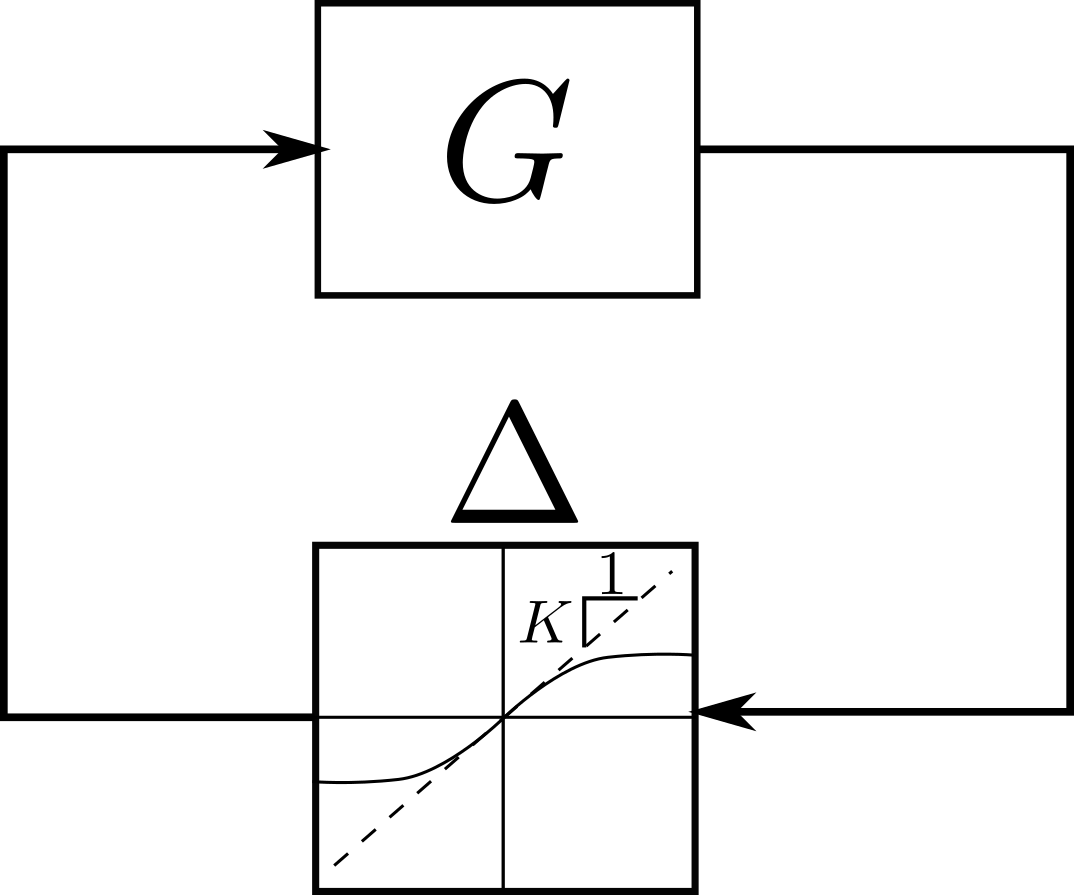


$$\mbox{ where } \hat{G}(z) = \frac{(z + 1)(10z + 9)}{(2z - 1)(5z - 1)(10z - 1)}$$


and $\Delta$ is a sigmoidal nonlinearity: $\Delta(p) = K \mathrm{arctan}(p)$

z = tf('z');
g = -(z + 1)*(10*z + 9)/(2*z - 1)/(5*z - 1)/(10*z - 1);
g_nom = toLft(ss(g));

We can first characterize this nonlinearity with the `DeltaBounded` class, which represents the set of all bounded nonlinear operators:

[dim_out, dim_in] = size(g_nom);
K = 0.75; % steepest slope in nonlinear function
del_bounded = DeltaBounded('bounded', dim_out, dim_in, K);
g_bounded = interconnect(toLft(del_bounded), g_nom).addPerformance({PerformanceStable})
exponential = 0.95; % Testing this exponential convergence rate 
options = AnalysisOptions('exponential', exponential);
result = iqcAnalysis(g_bounded, 'analysis_options', options);
result.exponential
result.valid

Here we can safely conclude that this nonlinear system has an exponential convergence rate at least as fast as $\rho = 0.95$. However, if we try to check for faster exponential convergence rates, we don't get a valid result:

options.exponential = 0.93;
result = iqcAnalysis(g_bounded, 'analysis_options', options);
result.exponential
result.valid

In fact, this nonlinear system does have a faster exponential convergence rate.  But our characterization of the nonlinearity $\Delta$ is too loose to make any tigheter conclusions.  Instead, let's characterize the sigmoid function with the set of memoryless sector-bounded nonlinearities:

lower_bound = 0;
upper_bound = K;
del_sector = DeltaSectorBounded('sector', dim_out, lower_bound, upper_bound);
g_sector = interconnect(toLft(del_sector), g_nom).addPerformance({PerformanceStable})
result = iqcAnalysis(g_sector, 'analysis_options', options);
result.exponential
result.valid

In fact, with this tighter characterization of the sigmoid nonlinearity, we can guarantee even faster convergence rates:

options.exponential = 0.71;
result = iqcAnalysis(g_sector, 'analysis_options', options)

### Providing specific multipliers

As discussed in the documentation "Conducting IQC analysis," users are capable of providing specific `MultiplierDelta` objects to improve their IQC analysis results:

rng(1)
g_rand = rss(dims, dims, dims); % A randomly generated state-space system
g_rand = 0.99 * g_rand / norm(g_rand, 'inf'); % Ensuring the system has Hinf norm less than 1
delay_max = 1/10; % seconds
delay = DeltaConstantDelay('delay', dims, delay_max);
g_delay = interconnect(toLft(delay), toLft([1; 1] * g_rand * [1, 1]));
g_delay = g_delay.addPerformance({PerformanceStable})
mult_del(2) = MultiplierConstantDelay(g_delay.delta.deltas{2}, 'discrete', false);
result = iqcAnalysis(g_delay, 'multipliers_delta', mult_del) % Not checking exponential rate

Here we see that the system with uncertain time-delays is robustly stable. However, when providing specific multipliers AND checking exponential convergence rates, it's important that each multiplier is constructed with the same desired exponential convergence rate:

exponential = 0.001;
options = AnalysisOptions('exponential', exponential);
try % The next line of code will throw an error
result = iqcAnalysis(g_delay, 'multipliers_delta', mult_del, 'analysis_options', options)
catch ME
    disp('Error thrown with message:')
    disp(ME.message)
end

Let's try again with a multiplier that is specified with the same exponential convergence rate:

mult_del(2) = MultiplierConstantDelay(g_delay.delta.deltas{2},...
                                      'discrete', false,...
                                      'exponential', exponential);
% No error will be thrown now
result = iqcAnalysis(g_delay, 'multipliers_delta', mult_del, 'analysis_options', options);
result.exponential
result.valid

In these examples we've seen how robust bounds on exponential convergence rates can be verified and how those bounds can be tightened by using tighter characterizations of the uncertainty/nonlinearity. While we can conduct exponential convergence analysis on numerous `Delta` subclasses, there are some subclasses that cannot support such analysis.  

For example, let's replace the uncertainty in the previous system with the set of bounded, dynamic, linear time-invariant systems (`DeltaDlti`):

dlti = DeltaDlti('dlti');
g_dlti = g_delay; g_dlti.delta.deltas{2} = dlti

We can see that the system is robustly stable:

result = iqcAnalysis(g_dlti)
result.valid

But when we attempt to verify a bound on the exponential convergence rate, an error is thrown:

exponential = 0.001;
options = AnalysisOptions('exponential', exponential);
try % The next line of code will throw an error
result = iqcAnalysis(g_dlti, 'analysis_options', options)
catch ME
    disp('Error thrown with message:')
    disp(ME.message)
end

## A note to developers

We welcome contributions that expand the `Delta` classes currently available in the toolbox so that exponential convergence analysis can be brought to bear on a wider variety of systems. The manner in which exponential convergence analysis affects standard IQC multipliers can be divided into three different groups:

- **Exponential IQCs are satisfied for any exponential rate if the standard IQC is satisfied** (i.e., (2C/2D) implies (3C/3D) for any value of `exponential`). This means that the field `exponential` will have no impact on the multiplier construction or its constraints.  Examples in this group can be seen in `DeltaBounded`, `DeltaSectorBounded`, `DeltaSlti`, `DeltaSltv`, and `DeltaSltvRateBnd`

- **Exponential IQCs impose modifications on the standard IQC multiplier and its constraints**. Examples in this group can be seen in `DeltaConstantDelay` and `DeltaConstantDelay2`

- **Exponential IQCs cannot be verified for the uncertainty set**. An example in this group can be seen in `DeltaDlti`

## Conclusion

Congrats! You've learned how to conduct robust exponential convergence analysis with `iqcToolbox`. This capability is useful in verifying convergence of optimization algorithms [1], developing robust MPC control laws [4], and synthesizing robust RNNs [5]. If you're interested in developing additional features, such as contributing additional uncertainty/disturbance/performance classes for this toolbox, check out the "Developer documentation."

## References

[1] Lessard, L., Recht, B., & Packard, A. (2016). Analysis and design of optimization algorithms via integral  quadratic constraints. *SIAM Journal on Optimization*, *26*(1), 57-95.

[2] Boczar, R., Lessard, L., & Recht,  B. (2015, December). Exponential convergence bounds using integral  quadratic constraints. In *2015 54th IEEE conference on decision and control (CDC)* (pp. 7516-7521). IEEE.

[3] Hu, B., & Seiler, P. (2016).  Exponential decay rate conditions for uncertain linear systems using  integral quadratic constraints. *IEEE Transactions on Automatic Control*, *61*(11), 3631-3637.

[4] Schwenkel, L., Köhler, J., Müller, M.  A., & Allgöwer, F. (2021). Model predictive control for linear  uncertain systems using integral quadratic constraints. *arXiv preprint arXiv:2104.05444*.

[5] Gu, F., Yin, H., Ghaoui, L. E., Arcak, M., Seiler, P., & Jin, M. (2021). Recurrent neural network  controllers synthesis with stability guarantees for partially observed  systems. *arXiv preprint arXiv:2109.03861*.